lambda_1 = 1;
lambda_2 = 1.2;
gamma = 0.05;
M = 750;
N = [500:75:1250, 1500, 1750, 2000:1000:10000, 20000:10000:100000];

F = @(x, lambda) 1 - exp(-x*lambda);

j = 1;
for n = N
    K_a = zeros(1, M); Xi_a = zeros(1, M); B_a = zeros(1, M);
    K_b = zeros(1, M); Xi_b = zeros(1, M); B_b = zeros(1, M);
    
    for i = 1:M
        X_a = exprnd(lambda_1, 1, n);
        X_b = exprnd(lambda_2, 1, n);
    
        K_a(i) = Kolmogorov(X_a, @(x) F(x, lambda_1), gamma);
        Xi_a(i) = XiXi(X_a, @(x) F(x, lambda_1), gamma);
        B_a(i) = EmptyBoxes(X_a, @(x) F(x, lambda_1), gamma);
        
        K_b(i) = Kolmogorov(X_b, @(x) F(x, lambda_1), gamma);
        Xi_b(i) = XiXi(X_b, @(x) F(x, lambda_1), gamma);
        B_b(i) = EmptyBoxes(X_b, @(x) F(x, lambda_1), gamma);
    end

    Kol(1, j) = sum(K_a) / length(K_a);
    Kol(2, j) = sum(K_b) / length(K_b);

    Xi(1, j) = sum(Xi_a) / length(Xi_a);
    Xi(2, j) = sum(Xi_b) / length(Xi_b);

    Box(1, j) = sum(B_a) / length(B_a);
    Box(2, j) = sum(B_b) / length(B_b);

    j = j + 1;
end

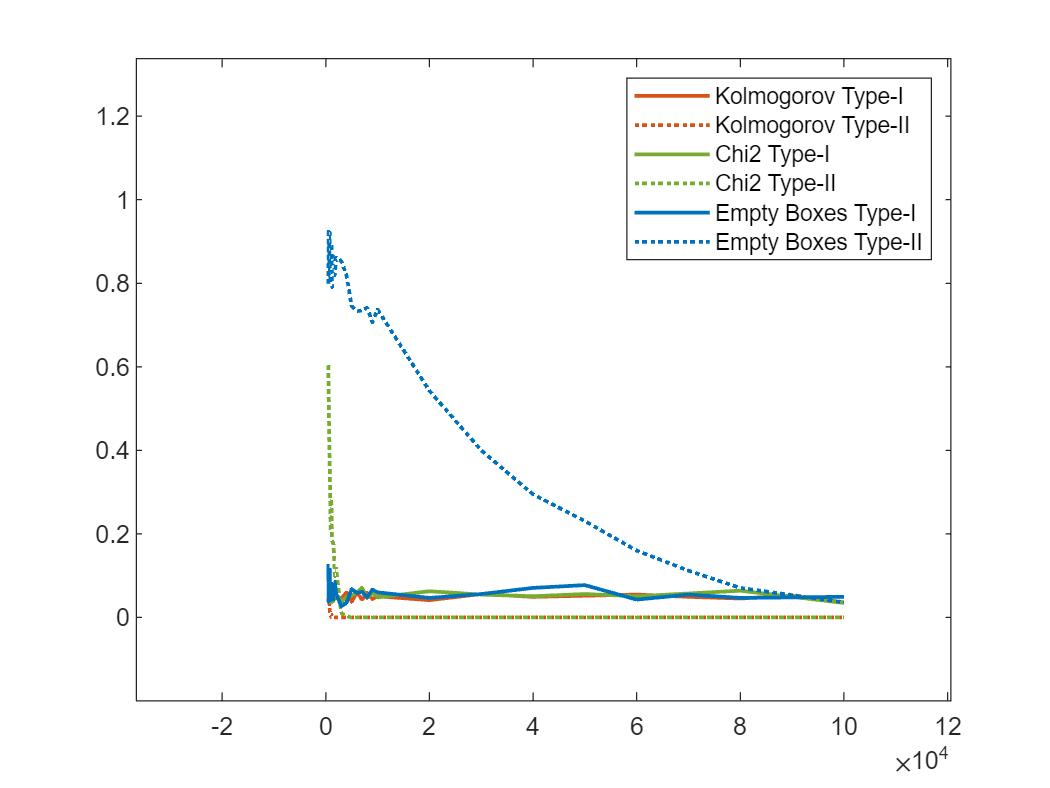

plot(N, 1 - Kol(1, :), "Color", '#D95319', 'LineWidth', 1.5);
hold on;
plot(N, Kol(2, :), "Color", '#D95319', 'LineWidth', 1.5, 'LineStyle',':')

plot(N, 1 - Xi(1, :), "Color", '#77AC30', 'LineWidth', 1.5)
plot(N, Xi(2, :), "Color", '#77AC30', 'LineWidth', 1.5, 'LineStyle',':')

plot(N, 1 - Box(1, :), "Color", '#0072BD', 'LineWidth', 1.5)
plot(N, Box(2, :), "Color", '#0072BD', 'LineWidth', 1.5, 'LineStyle',':')

legend('Kolmogorov Type-I', 'Kolmogorov Type-II', 'Chi2 Type-I', ...
    'Chi2 Type-II', 'Empty Boxes Type-I', 'Empty Boxes Type-II')

hold off;